# **14 Calculating R****0**** for non-randomly mixing populations**

 **Overview**

In the last practical, we explored the impact of different levels of vaccination coverage in populations with different contact patterns. In both, the age-specific proportion of individuals who were susceptible in the absence of vaccination were identical. However, the vaccine coverage needed to control transmission was different because of the different values of R0 in two choices.

The first part of this practical illustrates how you would calculate the next generation matrix and part II illustrates methods for calculating R0.

## **PART I: Calculating the next generation matrix**

Information required to calculate the basic reproduction number are given as below with average duration of infectious period of 11 days:

% Prac11에서 사용한 WAIFW B를 사용할 것이다.
clear; clc; close all;
N0 = 60000;     
N_y = 15000;    % population size of young group 
N_m = 15000;    % population size of middle-aged group
N_o = 30000;    % population size of old group
b = 1/(60*365);   % natural birth rate
d = 1/(30*365);   % natural death rate
a_y = 1/(15*365); % rate at which young individuals age
a_m = 1/(15*365); % rate at which middle-aged individuals age
f = 1/10;       % rate at which individuals become infectious
r = 1/11;       % rate at which infectious individuals recover

lambda_y = 0.000364; lambda_m = 0.000114; lambda_o = 0.000114;
S_y0 = 5012; S_m0 = 3083; S_o0 = 2739;
I_y0 = lambda_y * S_y0 / r;
I_m0 = lambda_m * S_m0 / r;
I_o0 = lambda_o * S_o0 / r;

% WAIFW
WAIFW = zeros(3,3);

beta3 = lambda_o / (I_y0+I_m0+I_o0);
beta2 = (lambda_m - I_o0 * beta3) / (I_y0+I_m0);
beta1 = (lambda_y - I_m0 * beta2 - I_o0 * beta3) / I_y0;

WAIFW(1:3,1:3) = 4.16e-6;
WAIFW(1:2,1:2) = 4.16e-6;
WAIFW(1,1) = 1.66e-5;

#### 1.How many secondary infectious persons among young individuals will occur as a result of the introduction of 

%NGM
NGM = WAIFW.*[N_y N_y N_y;N_m N_m N_m;N_o N_o N_o]./r;
fprintf(['i) 1 infectious young person : %.4f young people\n',...
         'ii) 1 infectious middle-aged person and  : %.4f young people\n',...
         'iii) 1 infectious old person? : %.4f young people\n'],NGM(1,1),NGM(1,2),sum(NGM(:,3)));

i) 1 infectious young person : 2.7390 young people
ii) 1 infectious middle-aged person and  : 0.6864 young people
iii) 1 infectious old person? : 2.7456 young people


#### 2. How many secondary infectious persons does each young, middle-aged and old infectious person generate in a totally susceptible population?

fprintf(['i) 1 infectious young person : %.4f people\n',...
         'ii) 1 infectious middle-aged person and  : %.4f people\n',...
         'iii) 1 infectious old person? : %.4f people\n'],sum(NGM(:,1)),sum(NGM(:,2)),sum(NGM(:,3)));

i) 1 infectious young person : 4.7982 people
ii) 1 infectious middle-aged person and  : 2.7456 people
iii) 1 infectious old person? : 2.7456 people


## **PART II: Calculating the basic reproduction number**

Introduced one infectious young individual into a totally susceptible population at the start to answer the question 1~4.

#### 1.What proportion of infectious persons in the first generation are young, middle-aged and old as a result of the introduction of one infectious young individual?

%Introduced one infectious young individual
inf = [1;0;0];
Q1 = NGM*inf;
unit_Q1 = Q1/sum(Q1);
fprintf(['proportion of infectious persons in the first generation (young): %.4f people\n',...
         'proportion of infectious persons in the first generation (middle) %.4f people\n',...
         'proportion of infectious persons in the first generation (old) %.4f people\n'],unit_Q1(1),unit_Q1(2),unit_Q1(3));

proportion of infectious persons in the first generation (young): 0.5708 people
proportion of infectious persons in the first generation (middle) 0.1431 people
proportion of infectious persons in the first generation (old) 0.2861 people


#### 2. How many secondary infectious persons resulted directly from the initial infectious person introduced into the population?

fprintf('Total infectious persons : %.4f',sum(Q1));

Total infectious persons : 4.7982

It is the summation of the first column of NGM shown in PART 1 because the initial infectious person introduced into the population is a young individual.

#### 3. What happens to the age distribution of the infectious persons in each generation after a few generations have occurred?

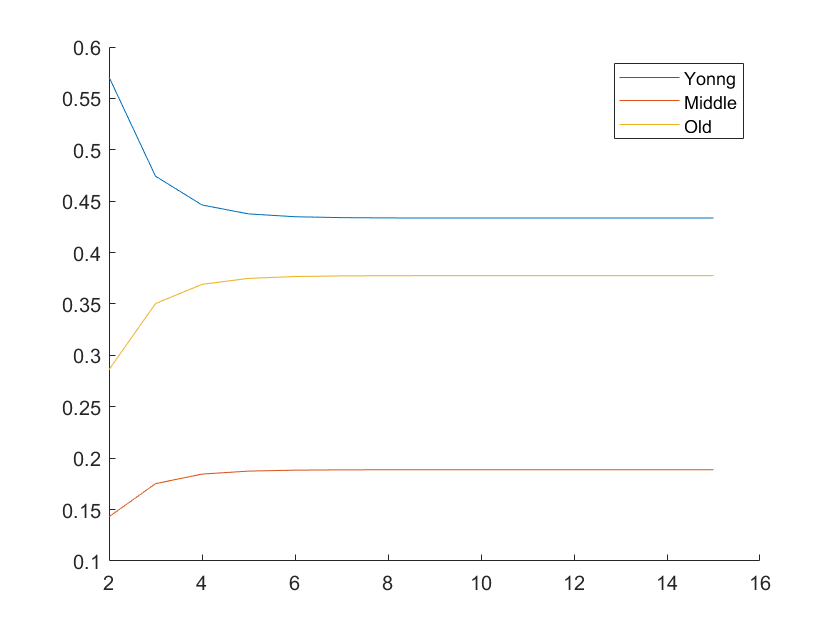

n=15;
New_inf = zeros(3,n);
New_inf(:,1) = inf;
for i = 1:n-1
    New_inf(:,i+1) = NGM*New_inf(:,i);
end
Gk = sum(New_inf,1);
prop_Inf = New_inf./Gk;
R0 = Gk(2:end)./Gk(1:end-1);
figure(1)
hold on;
plot(2:n,prop_Inf(:,2:n))
legend('Yonng','Middle','Old')
hold off;

fprintf(['Proportion age distribution of the infectious persons for young, middle, old people converges to %.f%%, %.f%%, %.f%% each.\n' ...
    'It started from young: %.f%%, middle: %.f%%, old: %.f%%.\n' ...
    'Proportion of the young slowly declined and simultaneously, ' ...
    'the proportion of the middle and old slowly increased.'], ...
    prop_Inf(1,end)*100,prop_Inf(2,end)*100,prop_Inf(3,end)*100,prop_Inf(1,2)*100,prop_Inf(2,2)*100,prop_Inf(3,2)*100)

Proportion age distribution of the infectious persons for young, middle, old people converges to 43%, 19%, 38% each.
It started from young: 57%, middle: 14%, old: 29%.
Proportion of the young slowly declined and simultaneously, the proportion of the middle and old slowly increased.

 4. What is the average number of secondary infectious persons resulting from each infectious person after a few generations have occurred?

fprintf(['The number of secondary infectious people resulting\n' ...
    'from each infectious person converges to Gk/Gk-1 = %.4f. \n' ...
    'We can guess that the basic reproduction number(R0) will be about %.4f.'],R0(end),R0(end))

The number of secondary infectious people resulting
from each infectious person converges to Gk/Gk-1 = 3.6356. 
We can guess that the basic reproduction number(R0) will be about 3.6356.

#### 5. Change the numbers of infectious persons introduced into the population at the start to take the following values:

#### i) 20, 50, 30 young, middle-aged and old infectious persons respectively.

#### ii) 0.5, 0.2 and 0.3 young, middle-aged and old infectious persons respectively.

#### How does changing the values for the numbers of infectious persons introduced into the population at the start alter your answer to Q3 and Q4?

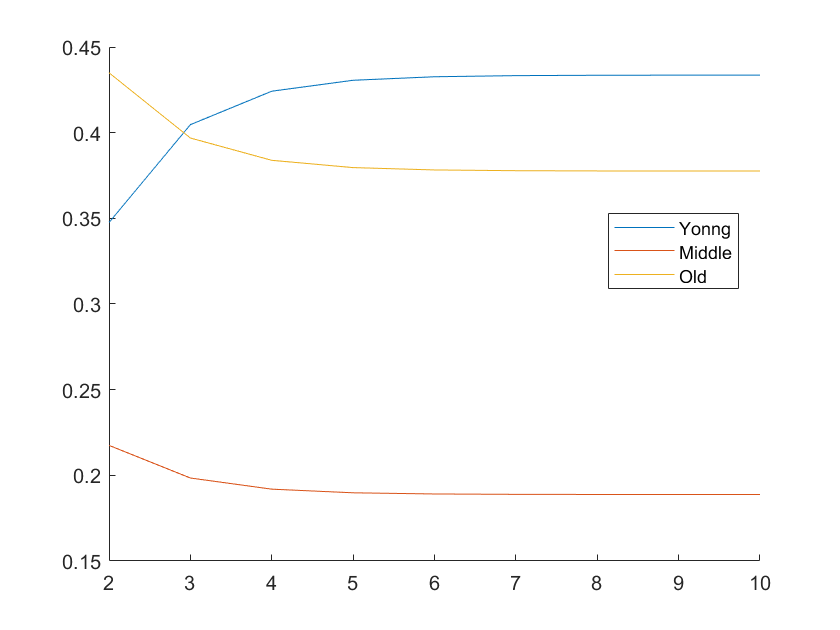

Proportion age distribution of the infectious persons for young, middle, old people converges to 43%, 19%, 38% each.
It started from young: 35%, middle: 22%, old: 43%.


R0 =     3.1561    3.4590    3.5762    3.6163    3.6294    3.6336    3.6350    3.6354    3.6355


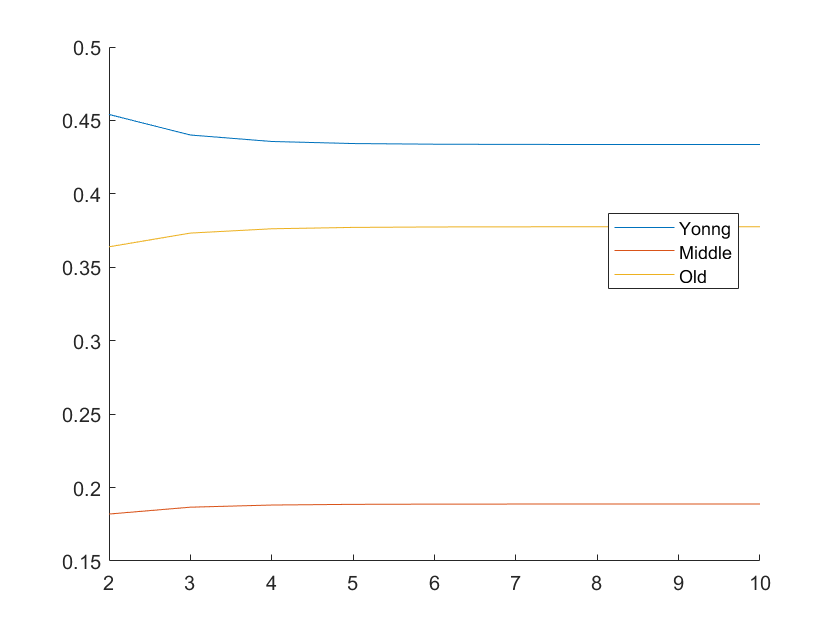

Proportion age distribution of the infectious persons for young, middle, old people converges to 43%, 19%, 38% each.
It started from young: 45%, middle: 18%, old: 36%.


R0 =     3.7719    3.6776    3.6489    3.6398    3.6370    3.6360    3.6358    3.6357    3.6356


infQ5 = [20,50,30;0.5,0.2,0.3];
[n,~] = size(infQ5);
for j = 1:n
    n=10;
    New_inf = zeros(3,n);
    New_inf(:,1) = infQ5(j,:);
    for i = 1:n-1
        New_inf(:,i+1) = NGM*New_inf(:,i);
    end
    Gk = sum(New_inf,1);
    prop_Inf = New_inf./Gk;
    R0 = Gk(2:end)./Gk(1:end-1);
    figure(j+1)
    hold on;
    plot(2:n,prop_Inf(:,2:n))
    legend('Yonng','Middle','Old')
    legend('Position',[0.7244,0.54048,0.15536,0.12143])
    hold off;
    fprintf(['Proportion age distribution of the infectious persons for young, middle, old people converges to %.f%%, %.f%%, %.f%% each.\n' ...
    'It started from young: %.f%%, middle: %.f%%, old: %.f%%.\n'], ...
    prop_Inf(1,end)*100,prop_Inf(2,end)*100,prop_Inf(3,end)*100,prop_Inf(1,2)*100,prop_Inf(2,2)*100,prop_Inf(3,2)*100)
    R0
end

#### 6. What are the maximum eigenvalue and the corresponding eigenvector of the next generation matrix? How are these related to your answer to the previous questions?

The maximum eigenvalue of the next generation matrix is 3.6356. The normalized eigenvector is [0.4336, 0.1888, 0.3776]’. The normalized eigenvector is the same as the converging age proportion distribution of the infectious people. 

## `VACCINATION`

#### 7. Change the value for the proportion of immune to see what happens to the average number of secondary infectious persons resulting from each infectious person after a few

#### generations have occurred if the following proportions of the population are immune:

#### i) 25%     ii) 50%     iii) 72.5%     ⅳ) 75%

vac = [25,50,72.5,75];
n = length(vac);
for j = 1:n
    n=10;
    New_inf = zeros(3,n);
    New_inf(:,1) = inf;
    for i = 1:n-1
        New_inf(:,i+1) = (1-vac(j)/100)*NGM*New_inf(:,i);
    end
    Gk = sum(New_inf,1);
    prop_Inf = New_inf./Gk;
    R0 = Gk(2:end)./Gk(1:end-1);
    fprintf('Proportion of immune: %.1f %%',vac(j))
    R0
end

Proportion of immune: 25.0 %

R0 =     3.5986    2.9380    2.7894    2.7463    2.7329    2.7287    2.7273    2.7269    2.7268


Proportion of immune: 50.0 %

R0 =     2.3991    1.9587    1.8596    1.8309    1.8220    1.8191    1.8182    1.8179    1.8179


Proportion of immune: 72.5 %

R0 =     1.3195    1.0773    1.0228    1.0070    1.0021    1.0005    1.0000    0.9999    0.9998


Proportion of immune: 75.0 %

R0 =     1.1995    0.9793    0.9298    0.9154    0.9110    0.9096    0.9091    0.9090    0.9089


The number of infectious people in each generation increases when the proportion of immune is 25% and 50%. The number of infectious people in each generation declines when the proportion of immune is 72.5% or greater than 72.5%. It is because the average number of secondary infectious persons resulting from each infectious person after a few

generations are about 2.7267, 1.8178, 0.9998, and 0.9089 when the proportion of immune is 25%, 50%, 72.5%, and 75% respectively. So, while R0 is bigger than 1 when the proportion of immune is 25% and 50%, R0 is smaller than 1 when the proportion of immune is 72.5% and 75%.